%% ELEC5305 Final Project
% Acoustic Cues and Listener Variability in Gender-Related Voice Perception
% Meiqi Song
% SID: 550200770

clear;
clc;
close all;

fprintf('ELEC5305 Final Project\n');

ELEC5305 Final Project


fprintf('Acoustic Cues and Listener Variability in Gender-Related Voice Perception\n\n');

Acoustic Cues and Listener Variability in Gender-Related Voice Perception




%% Part 1: Project folders
 
projectFolder = pwd;
dataFolder = fullfile(projectFolder,'Data');
figureFolder = fullfile(projectFolder,'Final_Results');

if ~isfolder(figureFolder)
    mkdir(figureFolder);
end

excelFile = fullfile( ...
    dataFolder, ...
    'MunsonDolquist2025_SummaryPerceptionData.xlsx');

if ~isfile(excelFile)
    error('Summary perception Excel file was not found in the Data folder.');
end


%% Part 2: Load published acoustic and perception data

Data = readtable( ...
    excelFile, ...
    'Sheet','Data', ...
    'VariableNamingRule','preserve');

fprintf('========== DATASET ==========\n');

========== DATASET ==========


fprintf('Stimuli in Excel file: %d\n',height(Data));

Stimuli in Excel file: 240


fprintf('Variables: %d\n\n',width(Data));

Variables: 42





%% Part 2.1: Read filename information

fileNames = string(Data.fileName);

n = height(Data);

TalkerID = NaN(n,1);
SentenceID = NaN(n,1);
ConditionCode = strings(n,1);
Condition = strings(n,1);

for i = 1:n

    name = fileNames(i);

    token = regexp( ...
        name, ...
        'POV_(\d+)_sent(\d+)_([XYZAB])', ...
        'tokens', ...
        'once');

    if isempty(token)
        error('Could not read filename: %s',name);
    end

    TalkerID(i) = str2double(token{1});
    SentenceID(i) = str2double(token{2});
    ConditionCode(i) = string(token{3});

end

Condition(ConditionCode=="X") = "Original";
Condition(ConditionCode=="Y") = "Raised F0";
Condition(ConditionCode=="A") = "Lowered F0";
Condition(ConditionCode=="Z") = "Lowered formants";
Condition(ConditionCode=="B") = "Raised formants";

Data.TalkerID = TalkerID;
Data.SentenceID = SentenceID;
Data.ConditionCode = ConditionCode;
Data.Condition = Condition;


%% Part 2.2: Check WAV files

wavFiles = dir(fullfile(dataFolder,'*.wav'));

fprintf('WAV files found: %d\n',length(wavFiles));

WAV files found: 242



AudioPath = strings(n,1);
MissingAudio = false(n,1);

for i = 1:n

    AudioPath(i) = fullfile( ...
        dataFolder, ...
        fileNames(i) + ".wav");

    MissingAudio(i) = ~isfile(AudioPath(i));

end

fprintf('Missing WAV files: %d\n\n',sum(MissingAudio));

Missing WAV files: 0




if any(MissingAudio)

    fprintf('Missing files:\n');

    disp(fileNames(MissingAudio));

end


%% Part 3: Listener response measures

% Group-averaged responses.
% The three listener groups are given equal weight here.

ManResponse = mean([ ...
    Data.("CHF-Man"), ...
    Data.("CHM-Man"), ...
    Data.("GSE-Man")],2,'omitnan');

WomanResponse = mean([ ...
    Data.("CHF-Woman"), ...
    Data.("CHM-Woman"), ...
    Data.("GSE-Woman")],2,'omitnan');

OtherResponse = mean([ ...
    Data.("CHF-OtherGender"), ...
    Data.("CHM-OtherGender"), ...
    Data.("GSE-OtherGender")],2,'omitnan');

NoResponse = mean([ ...
    Data.("CHF-no"), ...
    Data.("CHM-no"), ...
    Data.("GSE-no")],2,'omitnan');


responseMatrix = [ ...
    ManResponse, ...
    WomanResponse, ...
    OtherResponse, ...
    NoResponse];

[ListenerAgreement,dominantIndex] = ...
    max(responseMatrix,[],2);

responseLabels = [ ...
    "Man", ...
    "Woman", ...
    "Other gender", ...
    "No / uncertain"];

DominantResponse = ...
    responseLabels(dominantIndex).';


Data.ManResponse = ManResponse;
Data.WomanResponse = WomanResponse;
Data.OtherResponse = OtherResponse;
Data.NoResponse = NoResponse;
Data.ListenerAgreement = ListenerAgreement;
Data.DominantResponse = DominantResponse;


%% Part 4: Condition-level acoustic and perception summary

conditionOrder = [ ...
    "Original", ...
    "Lowered F0", ...
    "Raised F0", ...
    "Lowered formants", ...
    "Raised formants"];

numConditions = length(conditionOrder);

N = zeros(numConditions,1);
MeanF0 = zeros(numConditions,1);
MeanVTL = zeros(numConditions,1);
MeanManResponse = zeros(numConditions,1);
MeanAgreement = zeros(numConditions,1);

for c = 1:numConditions

    idx = Data.Condition == conditionOrder(c);

    N(c) = sum(idx);

    MeanF0(c) = ...
        mean(Data.f0(idx),'omitnan');

    MeanVTL(c) = ...
        mean(Data.sentVTL(idx),'omitnan');

    MeanManResponse(c) = ...
        mean(Data.ManResponse(idx),'omitnan');

    MeanAgreement(c) = ...
        mean(Data.ListenerAgreement(idx),'omitnan');

end


ConditionSummary = table( ...
    conditionOrder.', ...
    N, ...
    MeanF0, ...
    MeanVTL, ...
    MeanManResponse, ...
    MeanAgreement, ...
    'VariableNames', ...
    {'Condition','N','MeanF0_Hz','MeanVTL_cm', ...
     'MeanManResponse_percent','MeanAgreement_percent'});


fprintf('========== CONDITION SUMMARY ==========\n\n');

========== CONDITION SUMMARY ==========




disp(ConditionSummary);

        Condition         N     MeanF0_Hz    MeanVTL_cm    MeanManResponse_percent    MeanAgreement_percent
    __________________    __    _________    __________    _______________________    _____________________

    "Original"            48     130.82        16.925              62.998                     76.49        
    "Lowered F0"          48      118.8        17.007              63.361                    76.368        
    "Raised F0"           48      136.7        17.153              58.552                    74.661        
    "Lowered formants"    48     127.86        17.809              73.296                    82.587        
    "Raised formants"     48     142.56        15.686              38.503                    64.086        



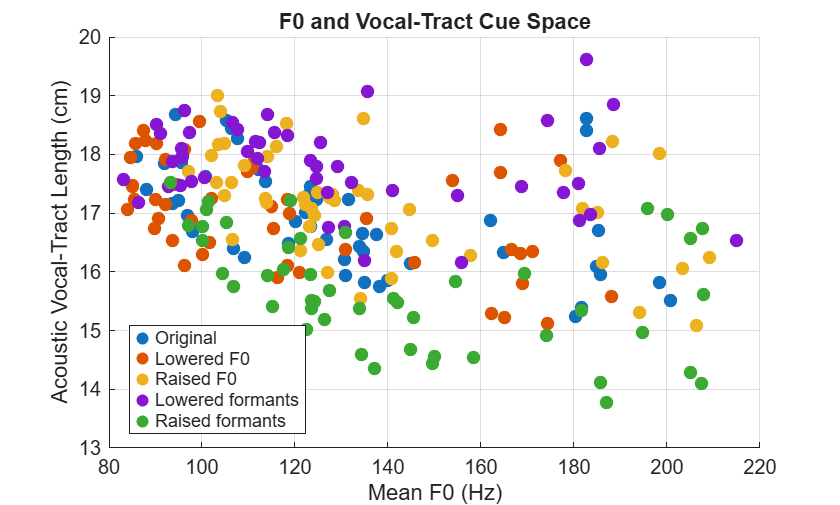



%% Figure 1: F0 and vocal-tract cue space

figure;
hold on;

for c = 1:numConditions

    idx = Data.Condition == conditionOrder(c);

    scatter( ...
        Data.f0(idx), ...
        Data.sentVTL(idx), ...
        45, ...
        'filled', ...
        'DisplayName',conditionOrder(c));

end

xlabel('Mean F0 (Hz)');
ylabel('Acoustic Vocal-Tract Length (cm)');
title('F0 and Vocal-Tract Cue Space');

legend('Location','best');
grid on;
hold off;

saveas( ...
    gcf, ...
    fullfile(figureFolder, ...
    'Figure1_Acoustic_Cue_Space.png'));

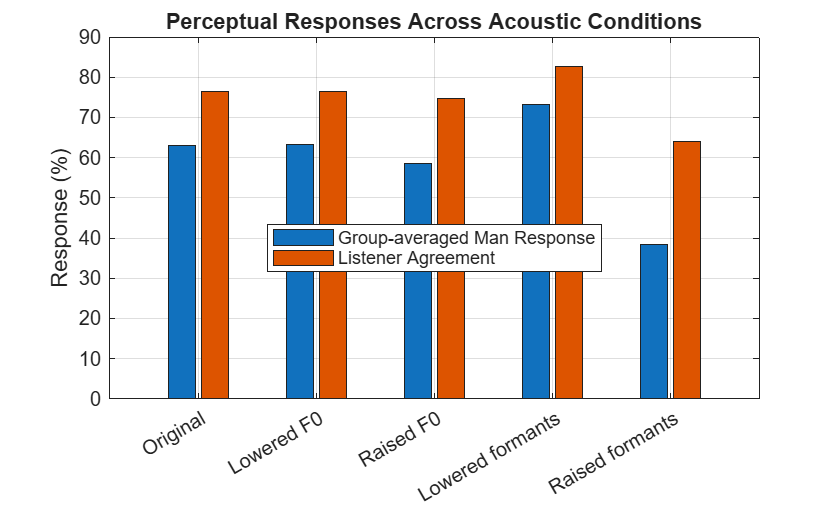



%% Figure 2: Manipulation condition and listener responses

figure;

bar( ...
    categorical(conditionOrder,conditionOrder), ...
    [MeanManResponse MeanAgreement]);

ylabel('Response (%)');

title( ...
    'Perceptual Responses Across Acoustic Conditions');

legend( ...
    {'Group-averaged Man Response', ...
     'Listener Agreement'}, ...
    'Location','best');

grid on;

saveas( ...
    gcf, ...
    fullfile(figureFolder, ...
    'Figure2_Condition_Perception.png'));

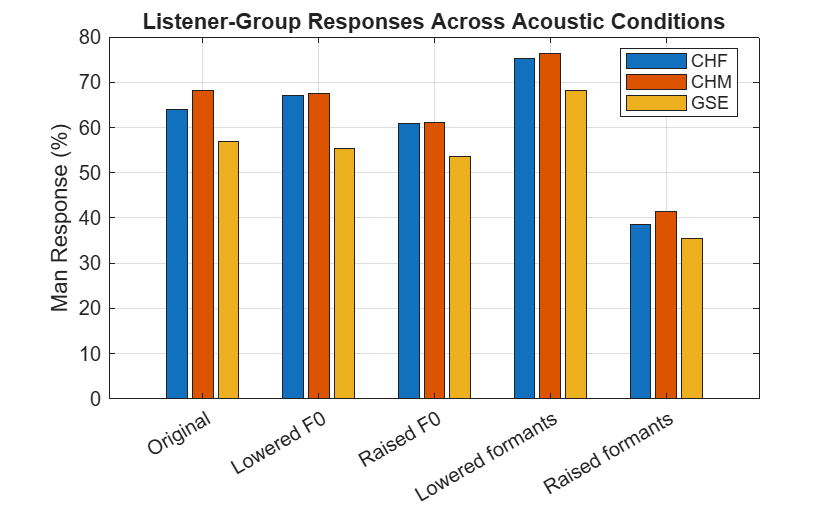



%% Part 5: Listener-group comparison

CHF_Man = zeros(numConditions,1);
CHM_Man = zeros(numConditions,1);
GSE_Man = zeros(numConditions,1);

for c = 1:numConditions

    idx = Data.Condition == conditionOrder(c);

    CHF_Man(c) = ...
        mean(Data.("CHF-Man")(idx),'omitnan');

    CHM_Man(c) = ...
        mean(Data.("CHM-Man")(idx),'omitnan');

    GSE_Man(c) = ...
        mean(Data.("GSE-Man")(idx),'omitnan');

end


figure;

bar( ...
    categorical(conditionOrder,conditionOrder), ...
    [CHF_Man CHM_Man GSE_Man]);

ylabel('Man Response (%)');

title( ...
    'Listener-Group Responses Across Acoustic Conditions');

legend( ...
    {'CHF','CHM','GSE'}, ...
    'Location','best');

grid on;

saveas( ...
    gcf, ...
    fullfile(figureFolder, ...
    'Figure3_Listener_Group_Comparison.png'));



%% Part 6: Exploratory cue-consistency analysis
%
% Lower F0 is treated as movement in the male-coded F0 direction.
% Larger aVTL is treated as movement in the male-coded vocal-tract direction.
%
% This is an exploratory analysis of whether agreement differs when
% the two acoustic cues point in a similar or conflicting direction.

zF0 = ...
    (Data.f0 - mean(Data.f0,'omitnan')) ./ ...
    std(Data.f0,'omitnan');

zVTL = ...
    (Data.sentVTL - mean(Data.sentVTL,'omitnan')) ./ ...
    std(Data.sentVTL,'omitnan');

F0MaleCue = -zF0;
VTLMaleCue = zVTL;

CueType = strings(n,1);

CueType(F0MaleCue .* VTLMaleCue >= 0) = ...
    "Cue-consistent";

CueType(F0MaleCue .* VTLMaleCue < 0) = ...
    "Cue-conflict";

Data.CueType = CueType;

consistentIdx = CueType == "Cue-consistent";
conflictIdx = CueType == "Cue-conflict";

consistentAgreement = ...
    mean(Data.ListenerAgreement(consistentIdx),'omitnan');

conflictAgreement = ...
    mean(Data.ListenerAgreement(conflictIdx),'omitnan');


fprintf('\n========== CUE-CONSISTENCY ANALYSIS ==========\n');


========== CUE-CONSISTENCY ANALYSIS ==========



fprintf( ...
    'Cue-consistent stimuli: %d\n', ...
    sum(consistentIdx));

Cue-consistent stimuli: 162



fprintf( ...
    'Cue-conflict stimuli: %d\n', ...
    sum(conflictIdx));

Cue-conflict stimuli: 78



fprintf( ...
    'Mean agreement - cue-consistent: %.2f%%\n', ...
    consistentAgreement);

Mean agreement - cue-consistent: 79.09%



fprintf( ...
    'Mean agreement - cue-conflict: %.2f%%\n\n', ...
    conflictAgreement);

Mean agreement - cue-conflict: 66.01%



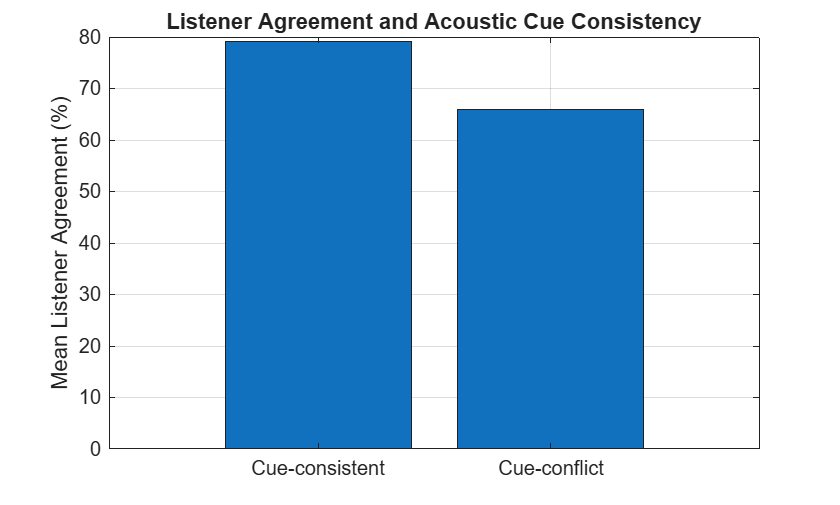



figure;

bar( ...
    categorical( ...
    ["Cue-consistent","Cue-conflict"], ...
    ["Cue-consistent","Cue-conflict"]), ...
    [consistentAgreement conflictAgreement]);

ylabel('Mean Listener Agreement (%)');

title( ...
    'Listener Agreement and Acoustic Cue Consistency');

grid on;

saveas( ...
    gcf, ...
    fullfile(figureFolder, ...
    'Figure4_Cue_Consistency.png'));



%% Part 7: Extract MFCC features from the 240 WAV files

numMFCC = 13;

MFCCMean = NaN(n,numMFCC);
MFCCStd = NaN(n,numMFCC);

fprintf('========== MFCC EXTRACTION ==========\n');

========== MFCC EXTRACTION ==========



for i = 1:n

    if MissingAudio(i)
        continue;
    end

    [x,fs] = audioread(AudioPath(i));

    if size(x,2) > 1
        x = mean(x,2);
    end

    x = x(:);
    x = x - mean(x);

    x = x / (max(abs(x)) + eps);

    try

        C = finalMFCC(x,fs);

        if size(C,1) <= 14 && size(C,2) > 14
            C = C.';
        end

        if size(C,2) == 14

            C = C(:,2:14);

        elseif size(C,2) > 13

            C = C(:,1:13);

        end

        if size(C,2) >= 13

            C = C(:,1:13);

            validRows = all(isfinite(C),2);

            C = C(validRows,:);

            if ~isempty(C)

                MFCCMean(i,:) = ...
                    mean(C,1,'omitnan');

                MFCCStd(i,:) = ...
                    std(C,0,1,'omitnan');

            end

        end

    catch ME

        fprintf( ...
            'MFCC failed for %s: %s\n', ...
            fileNames(i), ...
            ME.message);

    end

end

fprintf( ...
    'Valid MFCC recordings: %d / %d\n\n', ...
    sum(all(isfinite(MFCCMean),2)), ...
    n);

Valid MFCC recordings: 240 / 240





%% Part 8: Talker-independent model comparison

% Target:
% group-averaged proportion of listeners responding "Man"

Y = Data.ManResponse;

FeatureNames = [ ...
    "F0 only", ...
    "VTL only", ...
    "F0 + VTL", ...
    "F0 + VTL + MFCC"];

FeatureSets = cell(4,1);

FeatureSets{1} = Data.f0;

FeatureSets{2} = Data.sentVTL;

FeatureSets{3} = [ ...
    Data.f0 ...
    Data.sentVTL];

FeatureSets{4} = [ ...
    Data.f0 ...
    Data.sentVTL ...
    MFCCMean ...
    MFCCStd];


% 5-fold split by talker.
% Each talker remains entirely in one fold.

uniqueTalkers = unique(Data.TalkerID);

foldID = zeros(n,1);

for k = 1:length(uniqueTalkers)

    currentFold = mod(k-1,5) + 1;

    foldID(Data.TalkerID == uniqueTalkers(k)) = ...
        currentFold;

end


RMSE = NaN(4,1);
R2 = NaN(4,1);

Predictions = cell(4,1);

for m = 1:4

    X = FeatureSets{m};

    valid = ...
        all(isfinite(X),2) & ...
        isfinite(Y);

    prediction = NaN(n,1);


    for fold = 1:5

        trainIdx = ...
            valid & foldID ~= fold;

        testIdx = ...
            valid & foldID == fold;


        Xtrain = X(trainIdx,:);
        Xtest = X(testIdx,:);

        yTrain = Y(trainIdx);


        % Training-only normalisation

        mu = mean(Xtrain,1);
        sigma = std(Xtrain,0,1);

        sigma(sigma == 0) = 1;

        Xtrain = ...
            (Xtrain - mu) ./ sigma;

        Xtest = ...
            (Xtest - mu) ./ sigma;


        % Simple ridge regression

        lambda = 1;

        XtrainModel = ...
            [ones(size(Xtrain,1),1) Xtrain];

        XtestModel = ...
            [ones(size(Xtest,1),1) Xtest];


        penalty = ...
            eye(size(XtrainModel,2));

        penalty(1,1) = 0;


        beta = ...
            (XtrainModel' * XtrainModel + ...
            lambda * penalty) \ ...
            (XtrainModel' * yTrain);


        prediction(testIdx) = ...
            XtestModel * beta;

    end


    validPrediction = ...
        valid & isfinite(prediction);

    yTrue = Y(validPrediction);
    yPred = prediction(validPrediction);


    RMSE(m) = sqrt( ...
        mean((yTrue-yPred).^2));


    ssResidual = ...
        sum((yTrue-yPred).^2);

    ssTotal = ...
        sum((yTrue-mean(yTrue)).^2);

    R2(m) = ...
        1 - ssResidual/ssTotal;


    Predictions{m} = prediction;

end


ModelResults = table( ...
    FeatureNames.', ...
    RMSE, ...
    R2, ...
    'VariableNames', ...
    {'FeatureSet','RMSE','R2'});


fprintf('========== TALKER-INDEPENDENT MODEL RESULTS ==========\n\n');

========== TALKER-INDEPENDENT MODEL RESULTS ==========




disp(ModelResults);

       FeatureSet         RMSE       R2   
    _________________    ______    _______

    "F0 only"            18.775    0.71224
    "VTL only"           29.651     0.2823
    "F0 + VTL"           15.775    0.79685
    "F0 + VTL + MFCC"    18.408    0.72339



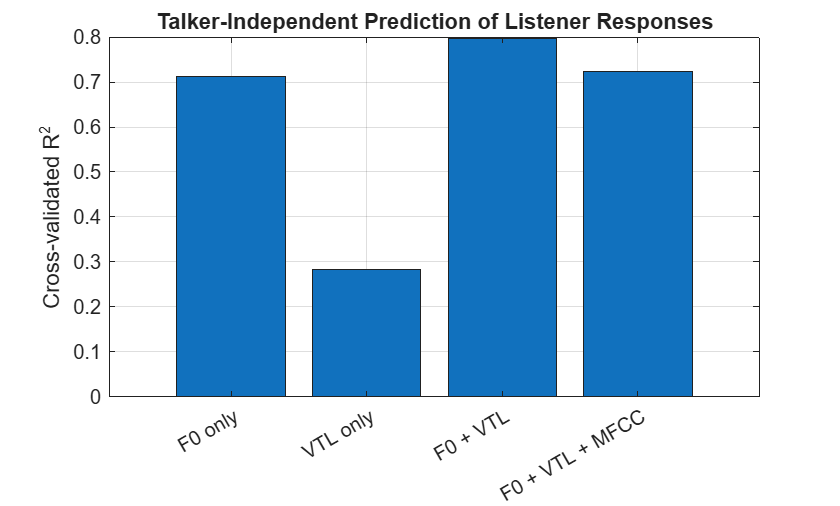



%% Figure 5: Model comparison

figure;

bar(categorical(FeatureNames,FeatureNames),R2);

ylabel('Cross-validated R^2');

title( ...
    'Talker-Independent Prediction of Listener Responses');

grid on;

saveas( ...
    gcf, ...
    fullfile(figureFolder, ...
    'Figure5_Model_Comparison.png'));



%% Part 9: Save Final Analysis Table

for c = 1:numMFCC

    Data.(sprintf('MFCC%d_Mean',c)) = ...
        MFCCMean(:,c);

    Data.(sprintf('MFCC%d_Std',c)) = ...
        MFCCStd(:,c);

end

writetable( ...
    Data, ...
    fullfile(projectFolder, ...
    'Final_Analysis_Table.csv'));


writetable( ...
    ConditionSummary, ...
    fullfile(projectFolder, ...
    'Final_Condition_Summary.csv'));


writetable( ...
    ModelResults, ...
    fullfile(projectFolder, ...
    'Final_Model_Results.csv'));


fprintf('\n========== COMPLETE ==========\n');


========== COMPLETE ==========


fprintf('Final analysis finished successfully.\n');

Final analysis finished successfully.


fprintf('Figures saved in Final_Results.\n');

Figures saved in Final_Results.


fprintf('Summary tables saved in the project folder.\n');

Summary tables saved in the project folder.



%% Local Function: MFCC Extraction

function C = finalMFCC(x,fs)

x = double(x(:));

% Pre-emphasis
x = filter([1 -0.97],1,x);

% Frame settings
frameLength = round(0.025*fs);
hopLength = round(0.010*fs);

if length(x) < frameLength
    x(end+1:frameLength) = 0;
end

numFrames = floor( ...
    (length(x)-frameLength)/hopLength) + 1;

nfft = 2^nextpow2(frameLength);

% Hamming window
n = (0:frameLength-1)';

w = 0.54 - 0.46*cos( ...
    2*pi*n/(frameLength-1));

frames = zeros(frameLength,numFrames);

for i = 1:numFrames
    idx = (i-1)*hopLength + (1:frameLength);
    frames(:,i) = x(idx).*w;
end

% Power spectrum
S = abs(fft(frames,nfft,1)).^2/nfft;

S = S(1:nfft/2+1,:);

% Mel filterbank
numFilters = 26;
numCoeffs = 13;

hzToMel = @(f) 2595*log10(1+f/700);
melToHz = @(m) 700*(10.^(m/2595)-1);

melPoints = linspace( ...
    hzToMel(0), ...
    hzToMel(fs/2), ...
    numFilters+2);

hzPoints = melToHz(melPoints);

freq = (0:nfft/2)*fs/nfft;

filterbank = zeros(numFilters,length(freq));

for m = 1:numFilters

    left = hzPoints(m);
    center = hzPoints(m+1);
    right = hzPoints(m+2);

    rising = (freq-left)/(center-left);
    falling = (right-freq)/(right-center);

    filterbank(m,:) = ...
        max(0,min(rising,falling));

end

melEnergy = filterbank*S;

logEnergy = log(max(melEnergy,realmin));

% DCT-II: keep coefficients 1 to 13
k = (1:numCoeffs)';
j = 0:numFilters-1;

D = sqrt(2/numFilters)*cos( ...
    pi/numFilters*(k*(j+0.5)));

C = (D*logEnergy).';

end

%% Part 10: Listener Agreement - Statistical Analysis
% Cluster bootstrap by talker
% 2000 bootstrap samples and 95% confidence intervals

fprintf('\n========== PART 10: STATISTICAL ANALYSIS ==========\n');


========== PART 10: STATISTICAL ANALYSIS ==========



rng(5305);

B = 2000;

talker = Data.TalkerID;
agreement = Data.ListenerAgreement;
cueType = string(Data.CueType);

valid = isfinite(talker) & isfinite(agreement);

consistent = cueType == "Cue-consistent" & valid;
conflict = cueType == "Cue-conflict" & valid;

talkerIDs = unique(talker(valid));
numTalkers = length(talkerIDs);

% Observed means
meanConsistent = mean(agreement(consistent));
meanConflict = mean(agreement(conflict));

observedDifference = meanConsistent - meanConflict;

fprintf('Number of talkers: %d\n',numTalkers);

Number of talkers: 20


fprintf('Consistent stimuli: %d\n',sum(consistent));

Consistent stimuli: 162


fprintf('Conflict stimuli: %d\n',sum(conflict));

Conflict stimuli: 78



fprintf('Mean consistent agreement: %.2f%%\n',meanConsistent);

Mean consistent agreement: 79.09%


fprintf('Mean conflict agreement: %.2f%%\n',meanConflict);

Mean conflict agreement: 66.01%


fprintf('Observed difference: %.2f percentage points\n', ...
    observedDifference);

Observed difference: 13.09 percentage points




%% Part 10.1: Talker-level bootstrap

% Columns:
% 1 = consistent mean
% 2 = conflict mean
% 3 = difference

bootstrapResults = NaN(B,3);

for b = 1:B

    sampledTalkers = talkerIDs( ...
        randi(numTalkers,numTalkers,1));

    sampledRows = [];

    for k = 1:numTalkers

        idx = find(talker == sampledTalkers(k) & valid);

        % Repeated talkers are deliberately included
        sampledRows = [sampledRows; idx];

    end

    sampledAgreement = agreement(sampledRows);
    sampledCue = cueType(sampledRows);

    idxC = sampledCue == "Cue-consistent";
    idxF = sampledCue == "Cue-conflict";

    if any(idxC) && any(idxF)

        bootstrapResults(b,1) = ...
            mean(sampledAgreement(idxC));

        bootstrapResults(b,2) = ...
            mean(sampledAgreement(idxF));

        bootstrapResults(b,3) = ...
            bootstrapResults(b,1) - bootstrapResults(b,2);

    end

end


%% Part 10.2: Calculate 95% Confidence Intervals
% Percentile interpolation without Statistics Toolbox

CI = NaN(3,2);

for j = 1:3

    values = bootstrapResults(:,j);
    values = sort(values(isfinite(values)));

    N = length(values);

    if N < 100
        error('Too few valid bootstrap samples.');
    end

    lowerPosition = 1 + 0.025*(N-1);
    upperPosition = 1 + 0.975*(N-1);

    CI(j,1) = interp1(1:N,values,lowerPosition);
    CI(j,2) = interp1(1:N,values,upperPosition);

end

fprintf('\n95%% Bootstrap Confidence Intervals:\n');


95% Bootstrap Confidence Intervals:



fprintf('Cue-consistent: [%.2f, %.2f]%%\n', ...
    CI(1,1),CI(1,2));

Cue-consistent: [71.63, 85.91]%



fprintf('Cue-conflict: [%.2f, %.2f]%%\n', ...
    CI(2,1),CI(2,2));

Cue-conflict: [60.10, 73.59]%



fprintf('Difference: [%.2f, %.2f] percentage points\n', ...
    CI(3,1),CI(3,2));

Difference: [5.07, 20.96] percentage points



if CI(3,1) > 0
    fprintf('The difference is positive across the 95%% bootstrap interval.\n');
elseif CI(3,2) < 0
    fprintf('The difference is negative across the 95%% bootstrap interval.\n');
else
    fprintf('The bootstrap interval includes zero.\n');
end

The difference is positive across the 95% bootstrap interval.




%% Part 10.3: Agreement differences within talkers

withinTalkerDifference = NaN(numTalkers,1);

for k = 1:numTalkers

    idx = talker == talkerIDs(k);

    idxC = idx & consistent;
    idxF = idx & conflict;

    if any(idxC) && any(idxF)

        withinTalkerDifference(k) = ...
            mean(agreement(idxC)) - ...
            mean(agreement(idxF));

    end

end

validTalkers = isfinite(withinTalkerDifference);

fprintf('\nTalkers with both cue types: %d / %d\n', ...
    sum(validTalkers),numTalkers);


Talkers with both cue types: 19 / 20



fprintf('Mean within-talker difference: %.2f points\n', ...
    mean(withinTalkerDifference(validTalkers)));

Mean within-talker difference: 5.78 points



fprintf('Talkers with positive differences: %d / %d\n', ...
    sum(withinTalkerDifference(validTalkers) > 0), ...
    sum(validTalkers));

Talkers with positive differences: 14 / 19


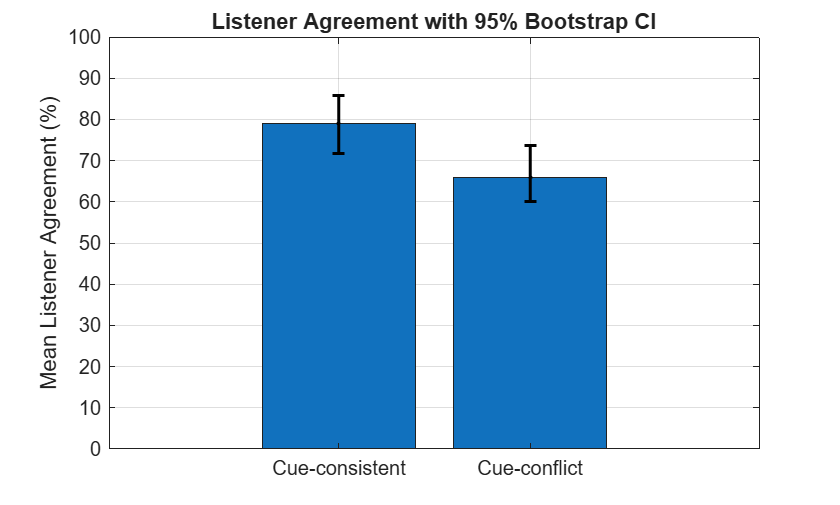



%% Part 10.4: Figure 6 - Bootstrap Confidence Intervals

figure;

x = [1 2];

means = [meanConsistent meanConflict];

bar(x,means);
hold on;

lowerError = means - CI(1:2,1)';
upperError = CI(1:2,2)' - means;

errorbar(x,means,lowerError,upperError, ...
    'k.','LineWidth',1.5);

set(gca,'XTick',x);
set(gca,'XTickLabel', ...
    {'Cue-consistent','Cue-conflict'});

ylabel('Mean Listener Agreement (%)');
title('Listener Agreement with 95% Bootstrap CI');

ylim([0 100]);
grid on;
hold off;

saveas(gcf,fullfile(figureFolder, ...
    'Figure6_Agreement_Bootstrap_CI.png'));

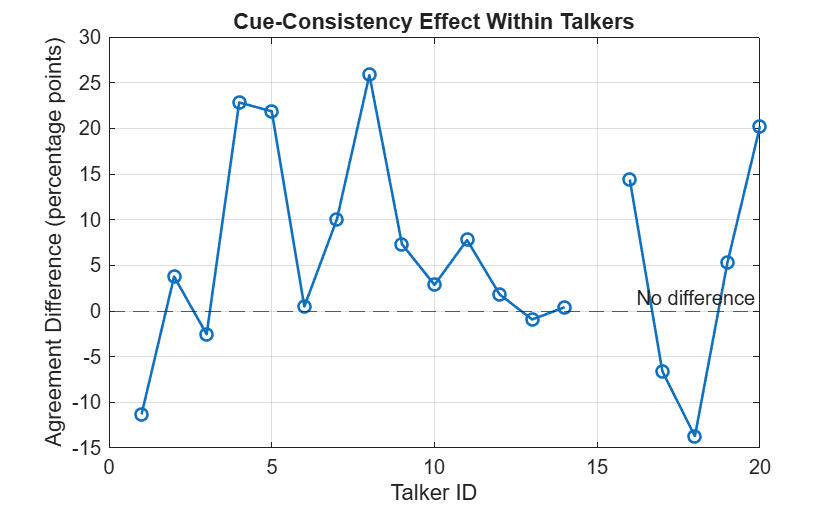



%% Part 10.5: Figure 7 - Within-Talker Differences

figure;

plot(talkerIDs,withinTalkerDifference, ...
    'o-','LineWidth',1.3);

hold on;

yline(0,'--','No difference');

xlabel('Talker ID');
ylabel('Agreement Difference (percentage points)');

title('Cue-Consistency Effect Within Talkers');

grid on;
hold off;

saveas(gcf,fullfile(figureFolder, ...
    'Figure7_Within_Talker_Differences.png'));



%% Part 10.6: Save Statistical Results

Group = ["Cue-consistent"; ...
         "Cue-conflict"; ...
         "Difference"];

Estimate = [meanConsistent; ...
            meanConflict; ...
            observedDifference];

BootstrapCI_Lower = CI(:,1);
BootstrapCI_Upper = CI(:,2);

BootstrapSummary = table( ...
    Group,Estimate,BootstrapCI_Lower,BootstrapCI_Upper);

writetable(BootstrapSummary, ...
    fullfile(figureFolder, ...
    'Table_Bootstrap_Results.csv'));

TalkerResults = table( ...
    talkerIDs,withinTalkerDifference, ...
    'VariableNames', ...
    {'TalkerID','AgreementDifference'});

writetable(TalkerResults, ...
    fullfile(figureFolder, ...
    'Table_WithinTalker_Results.csv'));

fprintf('\nPart 10 completed successfully.\n');


Part 10 completed successfully.


fprintf('Figures 6-7 and statistical tables saved.\n');

Figures 6-7 and statistical tables saved.



%% Part 11: Acoustic Condition Comparison
% Compare published acoustic and perception measurements
% across the five stimulus conditions.
% Comparisons are not matched by identical utterance.

fprintf('\n========== PART 11: ACOUSTIC CONDITION ANALYSIS ==========\n');


========== PART 11: ACOUSTIC CONDITION ANALYSIS ==========



figureFolder = fullfile(pwd,'Final_Results');
if ~isfolder(figureFolder)
    mkdir(figureFolder);
end

conditions11 = [
    "Original"
    "Lowered F0"
    "Raised F0"
    "Lowered formants"
    "Raised formants"
];

% Acoustic and perceptual measurements
X11 = [
    Data.f0, ...
    Data.sentVTL, ...
    Data.ManResponse, ...
    Data.ListenerAgreement
];

conditionLabels11 = string(Data.Condition);

N11 = zeros(5,1);
Mean11 = NaN(5,4);

%% Part 11.1: Condition-level means

for c = 1:5

    idx = conditionLabels11 == conditions11(c);

    N11(c) = sum(idx);

    if N11(c) == 0
        error('No recordings found for %s',conditions11(c));
    end

    Mean11(c,:) = mean(X11(idx,:),1,'omitnan');

end

ConditionResults11 = table( ...
    conditions11, ...
    N11, ...
    Mean11(:,1), ...
    Mean11(:,2), ...
    Mean11(:,3), ...
    Mean11(:,4), ...
    'VariableNames', ...
    {'Condition','N','MeanF0_Hz','MeanVTL_cm', ...
     'ManResponse_Percent','Agreement_Percent'});

fprintf('\nCondition-level results:\n');


Condition-level results:


disp(ConditionResults11);

        Condition         N     MeanF0_Hz    MeanVTL_cm    ManResponse_Percent    Agreement_Percent
    __________________    __    _________    __________    ___________________    _________________

    "Original"            48     130.82        16.925            62.998                 76.49      
    "Lowered F0"          48      118.8        17.007            63.361                76.368      
    "Raised F0"           48      136.7        17.153            58.552                74.661      
    "Lowered formants"    48     127.86        17.809            73.296                82.587      
    "Raised formants"     48     142.56        15.686            38.503                64.086      





%% Part 11.2: Differences from Original
% Descriptive differences between condition means.
% These are NOT same-utterance paired changes.

baseline11 = Mean11(1,:);

Delta11 = Mean11(2:5,:) - baseline11;

DeltaF0_Percent11 = ...
    100*Delta11(:,1)/baseline11(1);

DeltaVTL_Percent11 = ...
    100*Delta11(:,2)/baseline11(2);

DeltaMan_Points11 = Delta11(:,3);
DeltaAgreement_Points11 = Delta11(:,4);

Comparison11 = table( ...
    conditions11(2:5), ...
    N11(2:5), ...
    DeltaF0_Percent11, ...
    DeltaVTL_Percent11, ...
    DeltaMan_Points11, ...
    DeltaAgreement_Points11, ...
    'VariableNames', ...
    {'Condition','N', ...
     'F0_Difference_Percent', ...
     'VTL_Difference_Percent', ...
     'ManResponse_Difference_Points', ...
     'Agreement_Difference_Points'});

fprintf('\n========== DIFFERENCES FROM ORIGINAL ==========\n');


========== DIFFERENCES FROM ORIGINAL ==========


disp(Comparison11);

        Condition         N     F0_Difference_Percent    VTL_Difference_Percent    ManResponse_Difference_Points    Agreement_Difference_Points
    __________________    __    _____________________    ______________________    _____________________________    ___________________________

    "Lowered F0"          48           -9.1907                  0.48722                       0.36319                        -0.12153          
    "Raised F0"           48            4.4952                   1.3504                       -4.4458                         -1.8285          
    "Lowered formants"    48           -2.2652                   5.2241                        10.298                          6.0979          
    "Raised formants"     48            8.9713                  -7.3181    



%% Part 11.3: Within-talker condition comparison
% Use each talker's condition means.
% Different conditions may contain different sentences.

talkers11 = unique(Data.TalkerID);
nTalkers11 = numel(talkers11);

TalkerMeans11 = NaN(nTalkers11,5,4);

for t = 1:nTalkers11

    for c = 1:5

        idx = ...
            Data.TalkerID == talkers11(t) & ...
            conditionLabels11 == conditions11(c);

        if any(idx)

            values = mean(X11(idx,:),1,'omitnan');

            TalkerMeans11(t,c,:) = reshape(values,1,1,4);

        end

    end

end

N_Talkers11 = zeros(4,1);
WithinTalkerF0_11 = NaN(4,1);
WithinTalkerVTL_11 = NaN(4,1);
WithinTalkerMan_11 = NaN(4,1);
WithinTalkerAgreement_11 = NaN(4,1);

for c = 2:5

    originalMeans = reshape(TalkerMeans11(:,1,:),[],4);
    conditionMeans = reshape(TalkerMeans11(:,c,:),[],4);

    differences = conditionMeans - originalMeans;

    validTalkers = all(isfinite(differences),2);

    N_Talkers11(c-1) = sum(validTalkers);

    if any(validTalkers)

        averageDifference = ...
            mean(differences(validTalkers,:),1);

        WithinTalkerF0_11(c-1) = averageDifference(1);
        WithinTalkerVTL_11(c-1) = averageDifference(2);
        WithinTalkerMan_11(c-1) = averageDifference(3);
        WithinTalkerAgreement_11(c-1) = averageDifference(4);

    end

end

TalkerComparison11 = table( ...
    conditions11(2:5), ...
    N_Talkers11, ...
    WithinTalkerF0_11, ...
    WithinTalkerVTL_11, ...
    WithinTalkerMan_11, ...
    WithinTalkerAgreement_11, ...
    'VariableNames', ...
    {'Condition','TalkersWithBothConditions', ...
     'MeanF0_Difference_Hz', ...
     'MeanVTL_Difference_cm', ...
     'ManResponse_Difference_Points', ...
     'Agreement_Difference_Points'});

fprintf('\n========== WITHIN-TALKER COMPARISON ==========\n');


========== WITHIN-TALKER COMPARISON ==========


disp(TalkerComparison11);

        Condition         TalkersWithBothConditions    MeanF0_Difference_Hz    MeanVTL_Difference_cm    ManResponse_Difference_Points    Agreement_Difference_Points
    __________________    _________________________    ____________________    _____________________    _____________________________    ___________________________

    "Lowered F0"                     20                      -13.506                 -0.025449                     0.94472                         -2.1589          
    "Raised F0"                      20                        9.079                   0.15113                     -7.7228                         -3.2586          
    "Lowered formants"               20                      -1.1655                   0.76627                      8.1986             

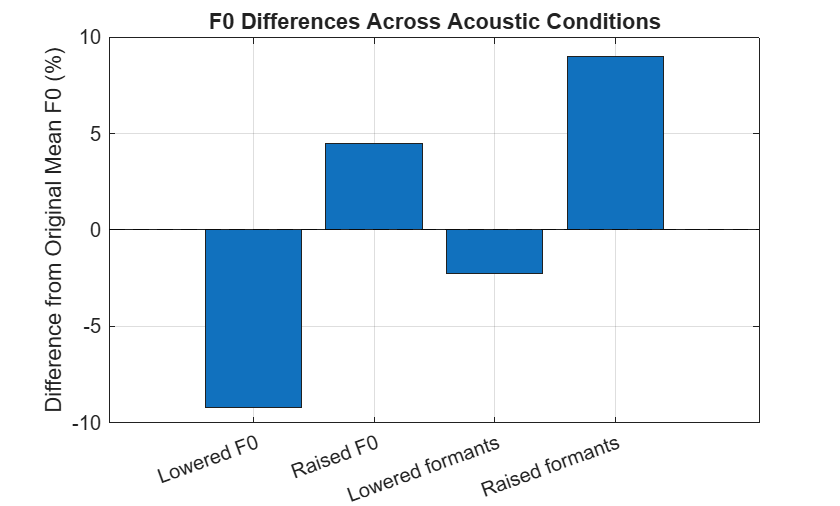

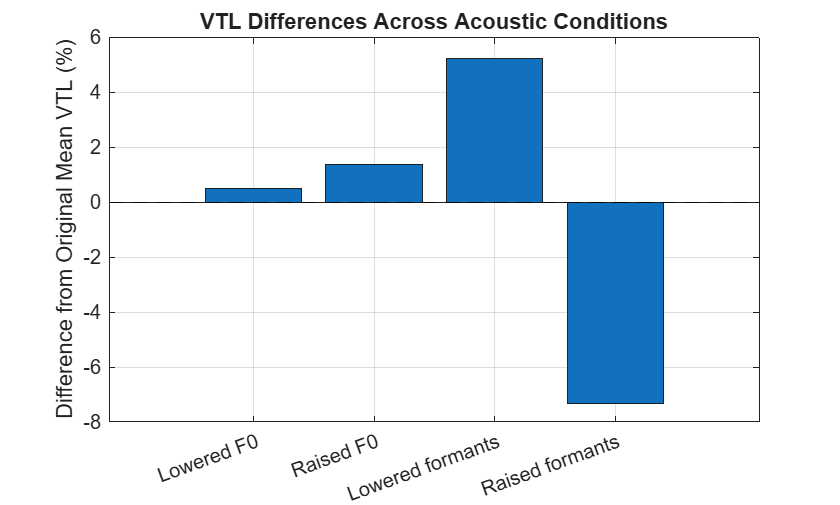

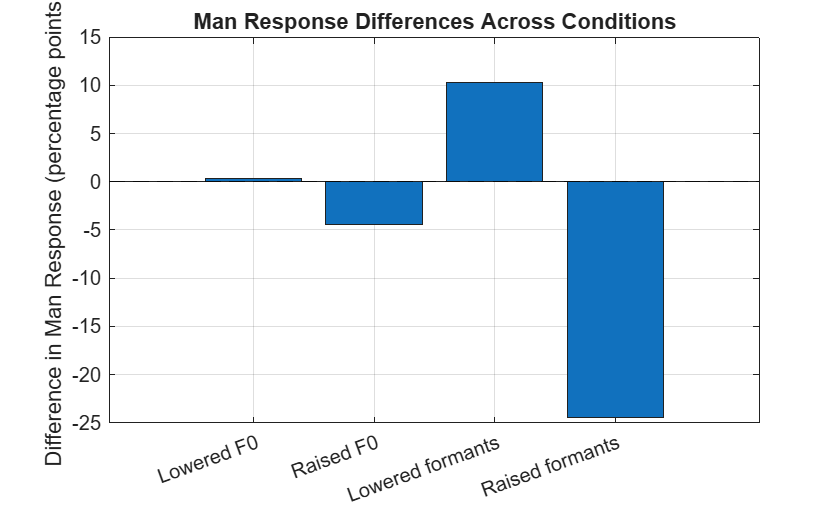

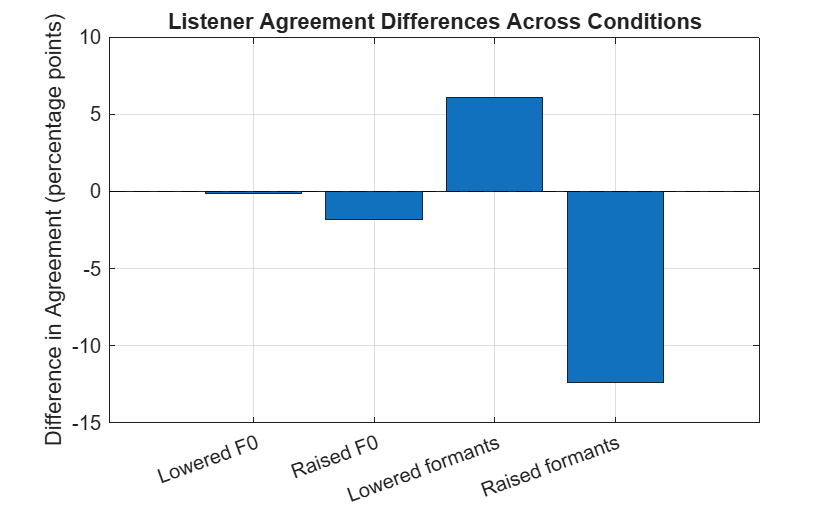



%% Part 11.4: Figures 8-11

plotValues11 = {
    DeltaF0_Percent11
    DeltaVTL_Percent11
    DeltaMan_Points11
    DeltaAgreement_Points11
};

plotTitles11 = {
    'F0 Differences Across Acoustic Conditions'
    'VTL Differences Across Acoustic Conditions'
    'Man Response Differences Across Conditions'
    'Listener Agreement Differences Across Conditions'
};

yLabels11 = {
    'Difference from Original Mean F0 (%)'
    'Difference from Original Mean VTL (%)'
    'Difference in Man Response (percentage points)'
    'Difference in Agreement (percentage points)'
};

fileNames11 = {
    'Figure8_F0_Condition_Comparison.png'
    'Figure9_VTL_Condition_Comparison.png'
    'Figure10_ManResponse_Comparison.png'
    'Figure11_Agreement_Comparison.png'
};

for j = 1:4

    figure;

    bar(1:4,plotValues11{j});

    hold on;
    yline(0,'k--');
    hold off;

    xticks(1:4);
    xticklabels(conditions11(2:5));
    xtickangle(20);

    ylabel(yLabels11{j});
    title(plotTitles11{j});
    grid on;

    saveas(gcf,fullfile(figureFolder,fileNames11{j}));

end



%% Part 11.5: Save results

writetable(ConditionResults11, ...
    fullfile(figureFolder,'Table_Condition_Results.csv'));

writetable(Comparison11, ...
    fullfile(figureFolder,'Table_Condition_Differences.csv'));

writetable(TalkerComparison11, ...
    fullfile(figureFolder,'Table_WithinTalker_Comparison.csv'));

fprintf('\nPart 11 completed successfully.\n');


Part 11 completed successfully.


fprintf('Condition comparisons and Figures 8-11 saved.\n');

Condition comparisons and Figures 8-11 saved.



%% Part 12: Talker-Level Analysis and Confidence Intervals
% Compare acoustic conditions using talker-level means.
% Different conditions may contain different sentences.
% Bootstrap resampling is performed by talker.

fprintf('\n========== PART 12: TALKER-LEVEL ANALYSIS ==========\n');


========== PART 12: TALKER-LEVEL ANALYSIS ==========



rng(5305);
B = 3000;

figureFolder = fullfile(pwd,'Final_Results');
if ~isfolder(figureFolder)
    mkdir(figureFolder);
end

conditionOrder12 = [
    "Original"
    "Lowered F0"
    "Raised F0"
    "Lowered formants"
    "Raised formants"
];

metricNames12 = [
    "F0"
    "VTL"
    "Man response"
    "Response concentration"
];

metricUnits12 = [
    "Hz"
    "cm"
    "percentage points"
    "percentage points"
];

X12 = [
    Data.f0 ...
    Data.sentVTL ...
    Data.ManResponse ...
    Data.ListenerAgreement
];

talkers12 = unique(Data.TalkerID);
nTalkers12 = numel(talkers12);

% Compute the mean for each talker and condition
talkerMeans12 = NaN(nTalkers12,5,4);

for t = 1:nTalkers12

    for c = 1:5

        idx = ...
            Data.TalkerID == talkers12(t) & ...
            string(Data.Condition) == conditionOrder12(c);

        if any(idx)

            for m = 1:4

                values = X12(idx,m);
                values = values(isfinite(values));

                if ~isempty(values)
                    talkerMeans12(t,c,m) = mean(values);
                end

            end

        end

    end

end

%% Part 12.1: Bootstrap differences from Original

% Four manipulated conditions x four measurements
numResults12 = 16;

Condition12 = strings(numResults12,1);
Metric12 = strings(numResults12,1);
Unit12 = strings(numResults12,1);

NTalkers12 = zeros(numResults12,1);

MeanDifference12 = NaN(numResults12,1);
CI_Lower12 = NaN(numResults12,1);
CI_Upper12 = NaN(numResults12,1);

row12 = 0;

for m = 1:4

    for c = 2:5

        row12 = row12 + 1;

        originalValues = ...
            talkerMeans12(:,1,m);

        modifiedValues = ...
            talkerMeans12(:,c,m);

        differences = ...
            modifiedValues - originalValues;

        differences = differences(isfinite(differences));

        n = numel(differences);

        Condition12(row12) = conditionOrder12(c);
        Metric12(row12) = metricNames12(m);
        Unit12(row12) = metricUnits12(m);
        NTalkers12(row12) = n;

        if n < 2
            continue;
        end

        MeanDifference12(row12) = mean(differences);

        % Cluster bootstrap: sample talkers with replacement
        samples = randi(n,n,B);

        bootstrapMeans = ...
            mean(differences(samples),1);

        bootstrapMeans = sort(bootstrapMeans);

        lowerPosition = 1 + 0.025*(B-1);
        upperPosition = 1 + 0.975*(B-1);

        CI_Lower12(row12) = ...
            interp1(1:B,bootstrapMeans,lowerPosition);

        CI_Upper12(row12) = ...
            interp1(1:B,bootstrapMeans,upperPosition);

    end

end

ConditionCI12 = table( ...
    Condition12, ...
    Metric12, ...
    Unit12, ...
    NTalkers12, ...
    MeanDifference12, ...
    CI_Lower12, ...
    CI_Upper12);

fprintf('\nCondition differences within talkers:\n');


Condition differences within talkers:


disp(ConditionCI12);

       Condition12                Metric12                  Unit12           NTalkers12    MeanDifference12    CI_Lower12    CI_Upper12
    __________________    ________________________    ___________________    __________    ________________    __________    __________

    "Lowered F0"          "F0"                        "Hz"                       20             -13.506          -15.979       -10.85  
    "Raised F0"           "F0"                        "Hz"                       20               9.079           5.7711       12.448  
    "Lowered formants"    "F0"                        "Hz"                       20             -1.1655          -3.9838        1.937  
    "Raised formants"     "F0"                        "Hz"                       


writetable(ConditionCI12, ...
    fullfile(figureFolder, ...
    'Table_TalkerLevel_Condition_CI.csv'));


%% Part 12.2: Cue-consistency analysis within talkers

cueType12 = string(Data.CueType);
agreement12 = Data.ListenerAgreement;

talkerDifference12 = NaN(nTalkers12,1);

for t = 1:nTalkers12

    currentTalker = Data.TalkerID == talkers12(t);

    idxConsistent = ...
        currentTalker & ...
        cueType12 == "Cue-consistent";

    idxConflict = ...
        currentTalker & ...
        cueType12 == "Cue-conflict";

    consistentValues = agreement12(idxConsistent);
    conflictValues = agreement12(idxConflict);

    consistentValues = ...
        consistentValues(isfinite(consistentValues));

    conflictValues = ...
        conflictValues(isfinite(conflictValues));

    if ~isempty(consistentValues) && ...
            ~isempty(conflictValues)

        talkerDifference12(t) = ...
            mean(consistentValues) - ...
            mean(conflictValues);

    end

end

validDifference12 = ...
    talkerDifference12(isfinite(talkerDifference12));

nValid12 = numel(validDifference12);

if nValid12 < 2
    error('Not enough talkers have both cue types.');
end

meanCueDifference12 = mean(validDifference12);

% Bootstrap the within-talker differences
samples12 = randi(nValid12,nValid12,B);

bootstrapCue12 = ...
    mean(validDifference12(samples12),1);

bootstrapCue12 = sort(bootstrapCue12);

cueCI_Lower12 = interp1( ...
    1:B,bootstrapCue12,1+0.025*(B-1));

cueCI_Upper12 = interp1( ...
    1:B,bootstrapCue12,1+0.975*(B-1));

fprintf('\n========== WITHIN-TALKER CUE ANALYSIS ==========\n');


========== WITHIN-TALKER CUE ANALYSIS ==========



fprintf('Talkers with both cue types: %d / %d\n', ...
    nValid12,nTalkers12);

Talkers with both cue types: 19 / 20



fprintf('Mean difference: %.2f percentage points\n', ...
    meanCueDifference12);

Mean difference: 5.78 percentage points



fprintf('95%% bootstrap CI: [%.2f, %.2f]\n', ...
    cueCI_Lower12,cueCI_Upper12);

95% bootstrap CI: [0.99, 10.65]



fprintf('Positive talker differences: %d / %d\n', ...
    sum(validDifference12 > 0),nValid12);

Positive talker differences: 14 / 19


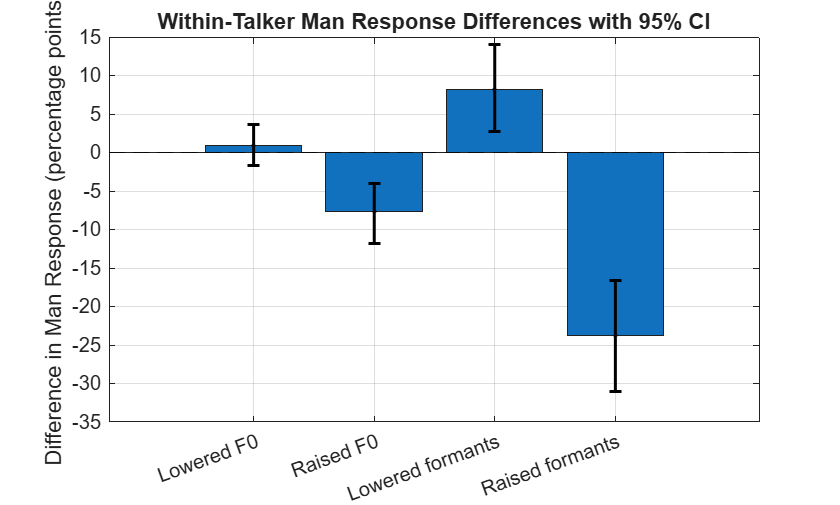



%% Part 12.3: Figure 12 - Man response with CI

idxMan12 = Metric12 == "Man response";

figure;

y = MeanDifference12(idxMan12);
lo = CI_Lower12(idxMan12);
hi = CI_Upper12(idxMan12);

x = 1:4;

bar(x,y);
hold on;

errorbar(x,y,y-lo,hi-y, ...
    'k.','LineWidth',1.5);

yline(0,'k--');

xticks(x);
xticklabels(conditionOrder12(2:5));
xtickangle(20);

ylabel('Difference in Man Response (percentage points)');
title('Within-Talker Man Response Differences with 95% CI');

grid on;
hold off;

saveas(gcf,fullfile(figureFolder, ...
    'Figure12_ManResponse_TalkerCI.png'));

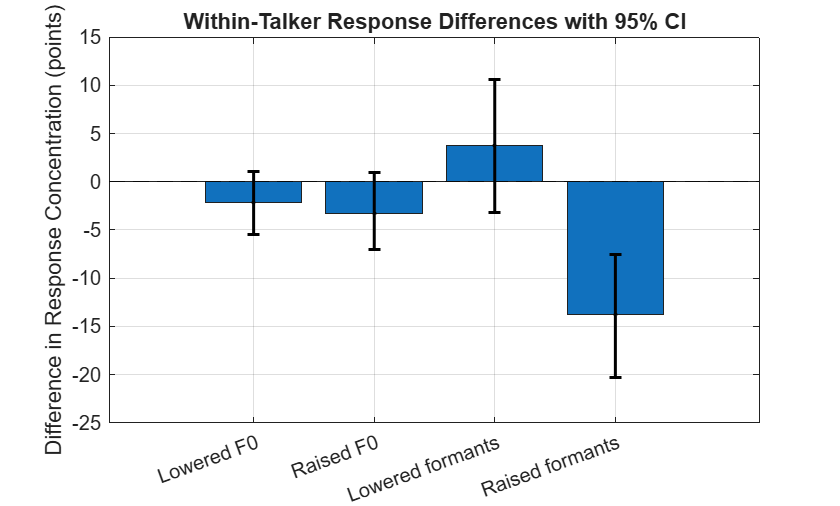



%% Part 12.4: Figure 13 - Response concentration with CI

idxAgreement12 = ...
    Metric12 == "Response concentration";

figure;

y = MeanDifference12(idxAgreement12);
lo = CI_Lower12(idxAgreement12);
hi = CI_Upper12(idxAgreement12);

bar(x,y);
hold on;

errorbar(x,y,y-lo,hi-y, ...
    'k.','LineWidth',1.5);

yline(0,'k--');

xticks(x);
xticklabels(conditionOrder12(2:5));
xtickangle(20);

ylabel('Difference in Response Concentration (points)');

title('Within-Talker Response Differences with 95% CI');

grid on;
hold off;

saveas(gcf,fullfile(figureFolder, ...
    'Figure13_ResponseConcentration_TalkerCI.png'));

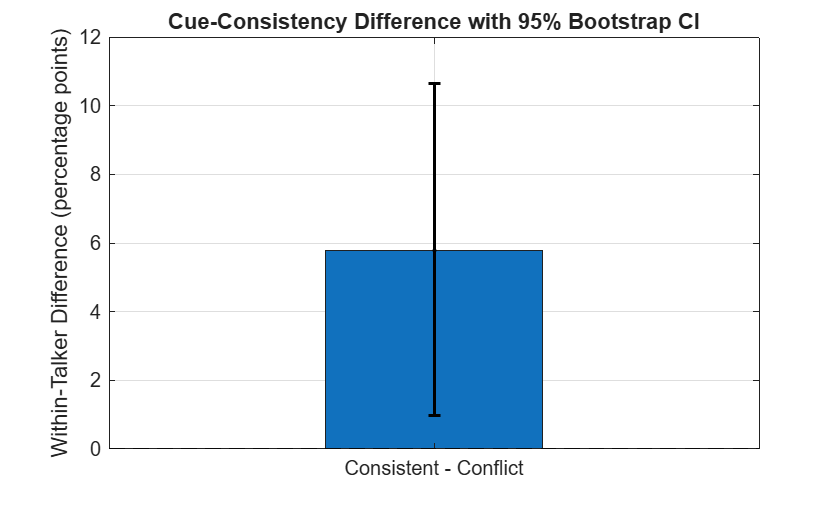



%% Part 12.5: Figure 14 - Cue consistency robustness

figure;

bar(1,meanCueDifference12);
hold on;

errorbar( ...
    1,meanCueDifference12, ...
    meanCueDifference12-cueCI_Lower12, ...
    cueCI_Upper12-meanCueDifference12, ...
    'k.','LineWidth',1.5);

yline(0,'k--');

xticks(1);
xticklabels({'Consistent - Conflict'});

ylabel('Within-Talker Difference (percentage points)');
title('Cue-Consistency Difference with 95% Bootstrap CI');

grid on;
hold off;

saveas(gcf,fullfile(figureFolder, ...
    'Figure14_CueConsistency_TalkerCI.png'));



%% Part 12.6: Save cue-consistency results

CueMeasure = "Within-talker consistent minus conflict";

NumTalkers = nValid12;
MeanDifference = meanCueDifference12;
CI_Lower = cueCI_Lower12;
CI_Upper = cueCI_Upper12;

CueSummary12 = table( ...
    CueMeasure, ...
    NumTalkers, ...
    MeanDifference, ...
    CI_Lower, ...
    CI_Upper);

writetable(CueSummary12, ...
    fullfile(figureFolder, ...
    'Table_CueConsistency_TalkerCI.csv'));

fprintf('\nPart 12 completed successfully.\n');


Part 12 completed successfully.


fprintf('Figures 12-14 and statistical tables saved.\n');

Figures 12-14 and statistical tables saved.
